### Turning radius on a slope

$radius = \frac{v^2}{g}[\frac{y.cos{\theta}}{h} - sin{\theta}]^{-1}$, where v is the velocity of the vehicle

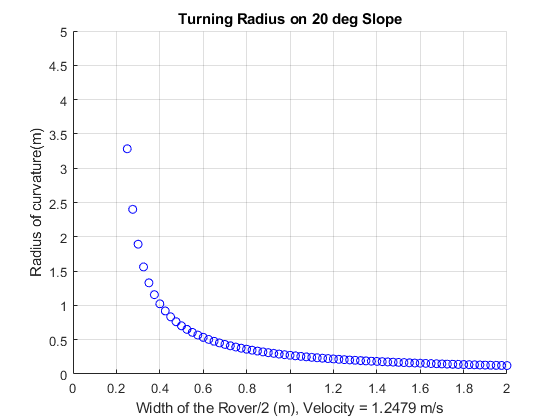

clear all
clc
g=3.711; % mars
theta_1 = 20;
v_limit_1 = 1.2479;
theta_2 = 0;
v_limit_2 = 4;
y_ = 0:0.025:2;
h_ = 0.5;
radius1=[];
radius2=[];
for i = 1:length(y_)
    radius_1 = (v_limit_1^2/g)*((y_(i)/h_).*cosd(theta_1) - sind(theta_1)).^(-1);
    radius1 = [radius1 radius_1];
    radius_2 = (v_limit_2^2/g)*((y_(i)/h_).*cosd(theta_2) - sind(theta_2)).^(-1);
    radius2 = [radius2 radius_2]; 
end

    figure;
    scatter(y_,radius1,'blue')
    xlabel('Width of the Rover/2 (m), Velocity = 1.2479 m/s')
    ylabel('Radius of curvature(m)')
    ylim([0 5])
    xlim([0 2])
    grid on
    title('Turning Radius on 20 deg Slope')

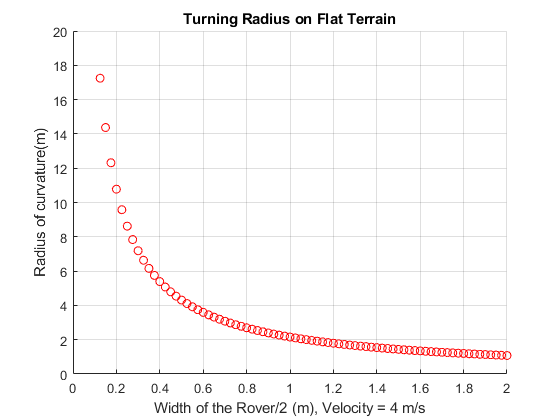

    figure;
    scatter(y_,radius2,'red')
    xlabel('Width of the Rover/2 (m), Velocity = 4 m/s')
    ylabel('Radius of curvature(m)')
    ylim([0 20])
    xlim([0 2])
    grid on
    title('Turning Radius on Flat Terrain')